# **..Authors**

*The work can be done in groups of up to 3 students. Please complete the following fields with your group number and list your names along with HDU ID numbers.*

`[HDU-AT3-25] Computer Vision`

 1. Li Xin 22320404

 2. Peng Yingrui 22320505

The task and guidelines were prepared by Andrei Zhdanov and Sergei Shavetov, ITMO University, 2025.

# **Practical Assignment No 2. Hough Transform**

Study of the Hough transformation to find of geometric primitives.

**Note.** Please note that when doing the practical assignment you are not allowed to use the “*Lenna*” image or any other image that was used either in this book or during the presentation

## Introduction

The main principle of the Hough transform is to find common *locus of points*. For example, this approach is used when designing a triangle along three given sides. At first one side of the triangle is first laid off, after that the ends of the segment are considered as the centers of circles with radii equal to the lengths of the second and third segments. The intersection of the two circles is the common locus of points, from where the segments are drawn to the ends of the first segment. In other words, a *voting* of two points was held in favor of the probable location of the third vertex of the triangle. As a result of "voting" "winning" was the point that got two "votes" (the points on the circles got one vote each, and outside them — zero). 

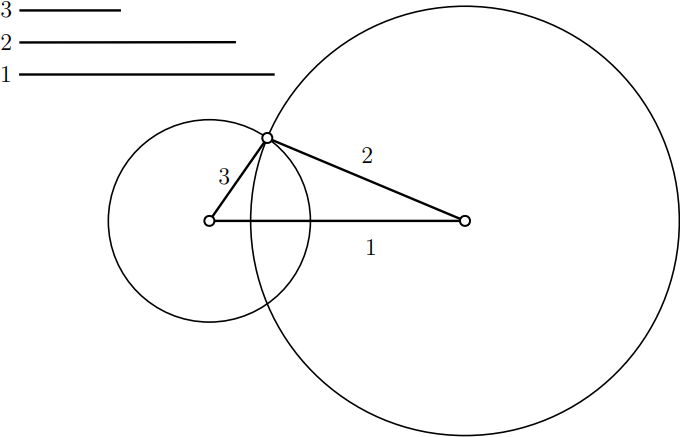

Figure 2.1 Design of a triangle by given three sides

Let’s generalize this idea for working with real data, when the image has a large number of special feature points participating in the vote. Let assume that it is necessary to search a circle of known radius 𝑅 in a binary point set, and in this set there may also be false points that do not lie on the desired circle. The set of possible circles centers for the desired radius around each characteristic point forms a circle of radius 𝑅, see Fig 2.2. Thus, the point corresponding to the maximum intersection of the number of circles will be the center of the required radius circle. 

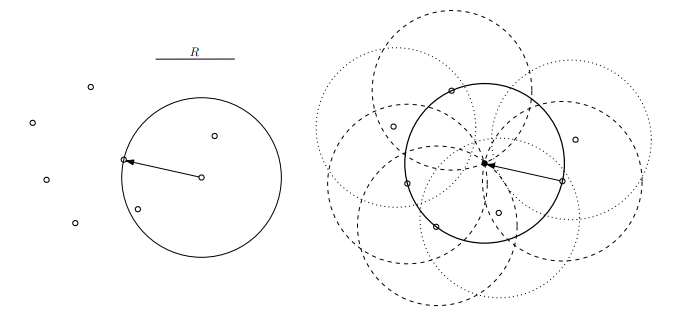

 Figure 2.2 Search a circle of known radius in a point set

The classical Hough transform, based on the considered point voting idea, was originally designed to select lines on binary images. The Hough transform uses the parameter space to search for geometric primitives. The most common parametric equation of lines is: 


$$y=kx+b,$$



$$x\cos{\Theta}+y\sin{\Theta}=\rho,$$


where $\rho$ — radius vector drawn from the origin to the line; $\Theta$ — inclination angle of the radius vector. Let the straight line in the Cartesian coordinate system be given by the first equation, from which it is easy to calculate the radius vector 𝜌 and angle Θ (secon equation). Then in the Hough parameter space the line will be represented by a point with coordinates ($\rho_0$,$\Theta_0$), see Fig. 2.3.

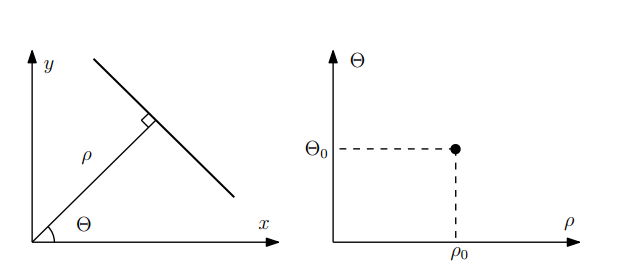

Figure 2.3 Representation of a straight line in Hough space

The Hough transform approach is for each point in the parameter space the number of votes given for it is summed up. Therefore, in discrete form, the Hough space is called *accumulator* and is a matrix 𝐴(𝜌,$\Theta$) that stores voting information. Through each point in the Cartesian coordinate system, an infinite number of straight lines can be drawn, the totality of which will generate a sinusoidal response function in the parameter space. Thus, any two sinusoidal response functions in the parameter space will intersect at the point (𝜌,$\Theta$) only if the points generating them in the initial space lie on a straight line, see fig. 2.4. Based on this, we can conclude that in order to find straight lines in the original space, it is necessary to find all the local maxima of the accumulator. 

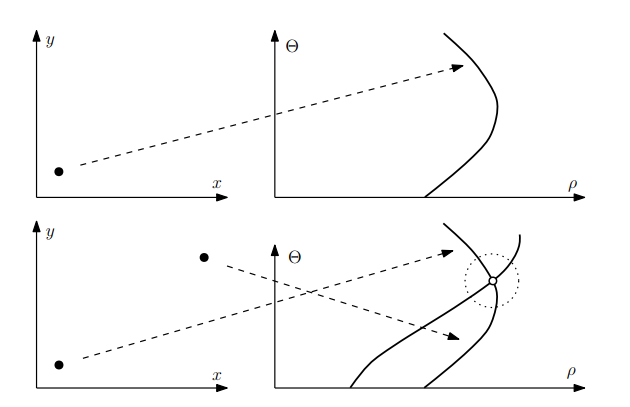

Figure 2.4. Voting procedure

The considered line search algorithm can be used in the same way to search for any other curve described in space by some function with a certain number of parameters 𝐹 = ($a_1 ,a_2 ,\ldotp \ldotp \ldotp ,a_n ,x,y$), which will only affect the dimension of the parameter space. Let us use the Hough transform to search for circles of a given radius 𝑅. It is known that a circle on a plane is described by the formula $(x-x_0)^2+(y-y_0)^2=R^2$ . The set of centers of all possible circles of radius 𝑅 passing through a feature point forms a circle of radius 𝑅 around that point. Due to this the response function in the Hough transform for finding circles is a circle of the same size centered at the voting point. Then, similarly to the previous case, it is necessary to find the local maxima of the accumulator function 𝐴(𝑥,𝑦) in the space of parameters (𝑥,𝑦), which will be the centers of the required circles.

The Hough transform is invariant to shift, scaling, and rotation. Taking into account that under projective transformations of three-dimensional space, straight lines always go only to straight lines (in the degenerate case, to points), the Hough transform makes it possible to detect lines invariantly not only to affine transformations of the plane, but also to the group of projective transformations in space.

## **Task 1. Search for Lines**

*Take three arbitrary images containing lines. Search for straight lines using various implementations of the Hough transform. Plot the found lines on the original image. Mark the start and end points of the lines. Determine the lengths of the shortest and longest lines, and calculate the number of lines found.*

### **1.1 Classic Hough Transform for Lines**

To execute the Hough line transform in MATLAB, first preprocess the image to detect edges using the Canny edge detector.

clear all;
clc

% Read an image
I = imread("images\pic1.png");
if isempty(I)
    error('Error reading the image.');
end

% Convert to grayscale if necessary
if size(I, 3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

In order to detect boundaries (edges) in the image, we will use the `edge()` function. It applies various methods of edge detection based on pixel intensity gradients, which allows you to find areas of sharp changes in brightness or colour.

The syntax `I_edge = edge(I, method, threshold, direction)`:

- `I` — the input image (usually in grayscale). 

- `method` — boundary detection method. Possible values:

- ` sobel` — Sobel method (default).

- ` prewitt` — Prewitt's method.

- ` roberts` — Roberts method.

- ` log` —  Laplace Gaussian method (LoG)

- ` zerocross` — zero-crossing detection method.

- ` canny` — Canny's method (more complex and accurate).

The Canny method computes the gradient of input image using the derivative of the Gaussian filter. It then finds edges by looking for the local maxima of the gradient. This method uses two thresholds to detect the strong and weak edges. The weak edges are part of the output only if they are connected to strong edges. The block outputs a binary image of the edge detections for this method.

- `threshold` — threshold value for boundary detection. Pixels with gradient below this value are not considered as boundaries.

- `direction` — irection for methods that support this property (e.g. `sobel`, `prewitt`):

- ` horizontal` — only horizontal boundaries.

- ` vertical` — only vertical boundaries.

- ` both` — both directions (default).

`I_edge` — output binary image where the pixels belonging to the boundaries have a value of 1 (white) and the rest have a value of 0 (black).

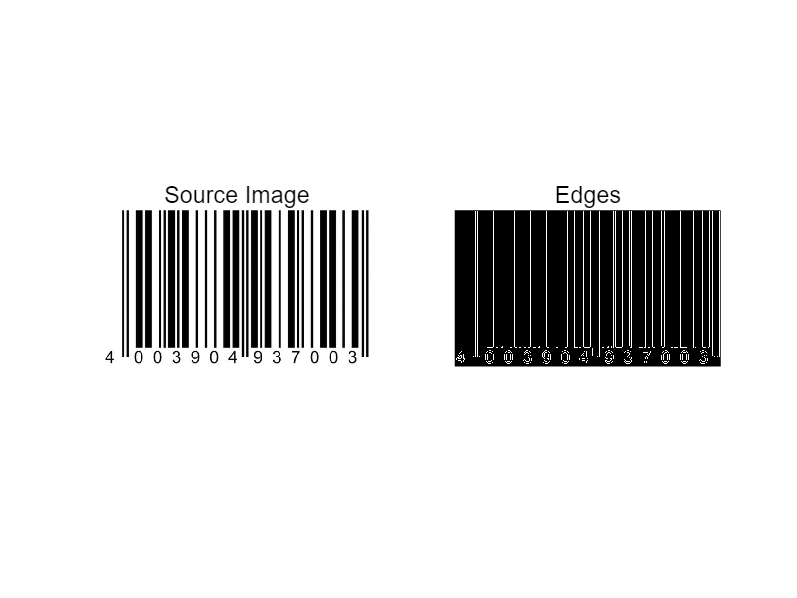

% Detect edges using the Canny edge detector
I_edge = edge(I_gray, 'canny');


% Display the original and edge-detected images
figure;
subplot(1, 2, 1); imshow(I); title('Source Image');
subplot(1, 2, 2); imshow(I_edge); title('Edges');

Next, compute the Hough transform and identify peaks and lines in the image by the functions `houghpeaks()` and `houghlines()`, respectively.

Let's take a closer look at the function parameters.

`peaks = houghpeaks(H, 'Threshold')` locates peaks in the Hough transform matrix, **H**, generated by the [`hough`](https://www.mathworks.com/help/releases/R2024a/images/ref/hough.html) function. 

**numpeaks** specifies the maximum number of peaks to identify. The function returns `peaks` a matrix that holds the row and column coordinates of the peaks.

`lines = houghlines(I_edge, theta, rho, peaks)` extracts line segments in the image **I_edge** associated with particular bins in a **Hough transform**. 

`theta` and `rho` are vectors returned by function `hough()`. 

`peaks` is a matrix returned by the `houghpeaks()` function that contains the row and column coordinates of the **Hough transform** bins to use in searching for line segments. The return value `lines` contains information about the extracted line segments:

- `point1` — coordinates of the starting point of the line [x1, y1].

- `point2` — coordinates of the end point of the line [x2, y2].

- `theta `— line slope angle (in degrees).

- `rho `— distance from the coordinate origin to the line (in pixels).

% Compute the Hough transform
[H, theta, rho] = hough(I_edge);

% Find peaks in the Hough transform accumulator
peaks = houghpeaks(H, 20, 'Threshold', 25);

% Extract lines using the Hough lines function
lines = houghlines(I_edge, theta, rho, peaks);

Finally, plot the detected lines on the original image:

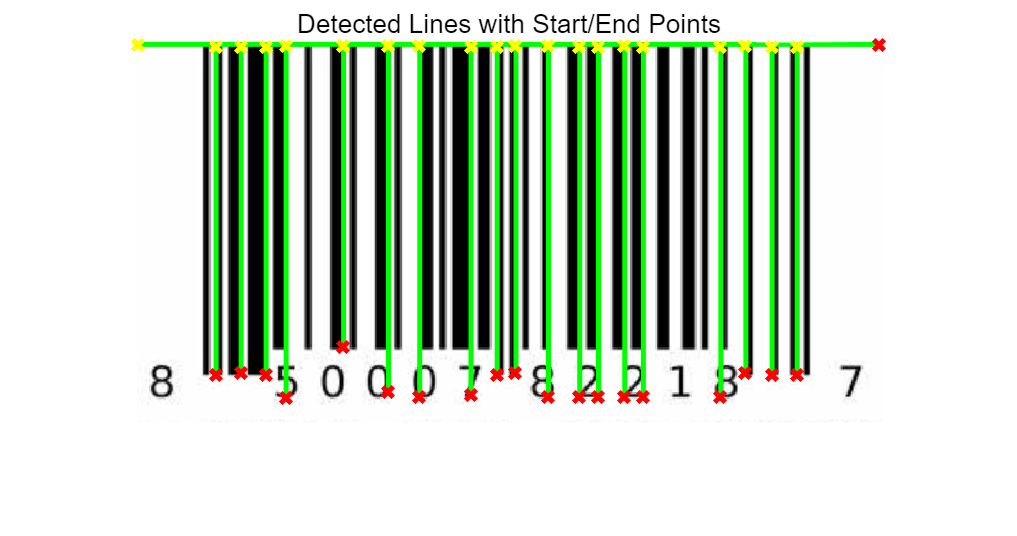

% Create a copy of the original image to draw lines on
I_lines = I;

% Plot the detected lines
figure;
imshow(I_lines); hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:, 1), xy(:, 2), 'LineWidth', 2, 'Color', 'green');
    
    % Mark the start and end points
    plot(xy(1, 1), xy(1, 2), 'x', 'LineWidth', 2, 'Color', 'yellow');
    plot(xy(2, 1), xy(2, 2), 'x', 'LineWidth', 2, 'Color', 'red');
end
title('Detected Lines with Start/End Points');
hold off;

Let's calculate and display statistical information:

% Calculate the number of lines, shortest, and longest lengths
num_lines = length(lines);
line_lengths = arrayfun(@(x) norm(x.point1 - x.point2), lines);
shortest_length = min(line_lengths);
longest_length = max(line_lengths);

% Display the results
fprintf('Found %d lines.\n', num_lines);

Found 20 lines.


fprintf('The shortest line length is %.2f pixels.\n', shortest_length);

The shortest line length is 287.00 pixels.


fprintf('The longest line length is %.2f pixels.\n', longest_length);

The longest line length is 322.00 pixels.


# ***Self-work***

Take **three** arbitrary images and execute the classic Hough transform. Display the found lines and print their number. 

***Notes. ****You may have to change the Hough transform parameters to match your images.*

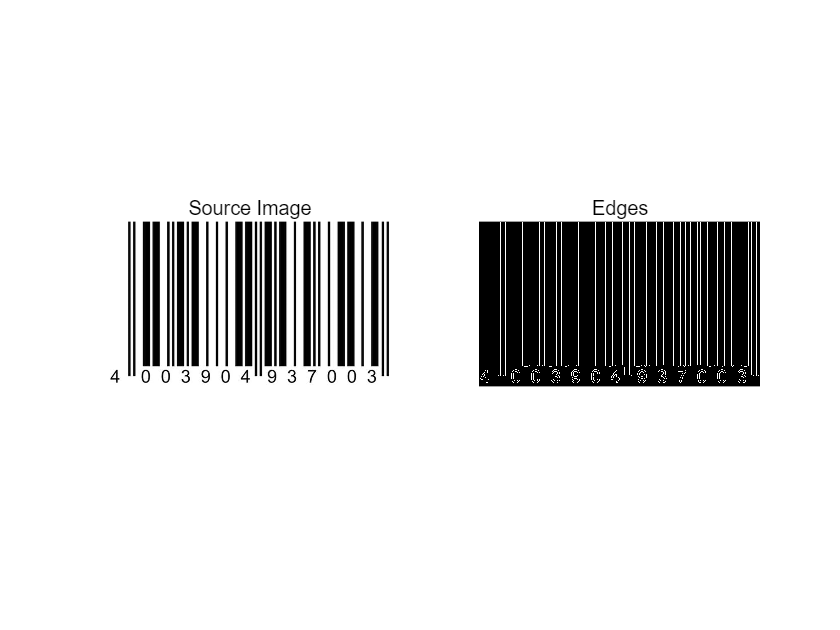

% TODO Place your solution here
% Read three different images
%% 初始化设置
clear all; close all; clc;
imagePaths = {'images/pic1.png', 'images/pic2.png', 'images/pic3.png'};
% Detect edges using the Canny edge detector
I = imread(imagePaths{1});
if isempty(I)
    error('Error reading the image.');
end

% Convert to grayscale if necessary
if size(I, 3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end
% Detect edges using the Canny edge detector
I_edge = edge(I_gray, 'canny', [0.1 0.25]);

% Display the original and edge-detected images
figure;
subplot(1, 2, 1); imshow(I); title('Source Image');
subplot(1, 2, 2); imshow(I_edge); title('Edges');

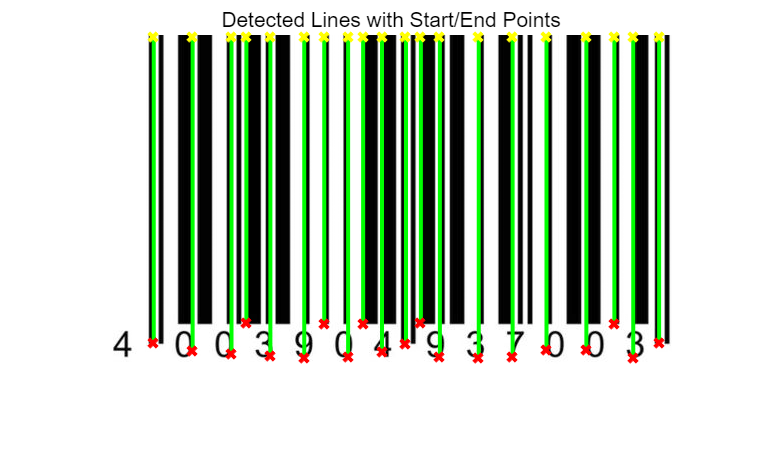

% Compute the Hough transform
[H, theta, rho] = hough(I_edge);

% Find peaks in the Hough transform accumulator
peaks = houghpeaks(H, 20, 'Threshold', 25);

% Extract lines using the Hough lines function
lines = houghlines(I_edge, theta, rho, peaks);
% Create a copy of the original image to draw lines on
I_lines = I;
% Plot the detected lines
figure;
imshow(I_lines); hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:, 1), xy(:, 2), 'LineWidth', 2, 'Color', 'green');
    
    % Mark the start and end points
    plot(xy(1, 1), xy(1, 2), 'x', 'LineWidth', 2, 'Color', 'yellow');
    plot(xy(2, 1), xy(2, 2), 'x', 'LineWidth', 2, 'Color', 'red');
end
title('Detected Lines with Start/End Points');
hold off;

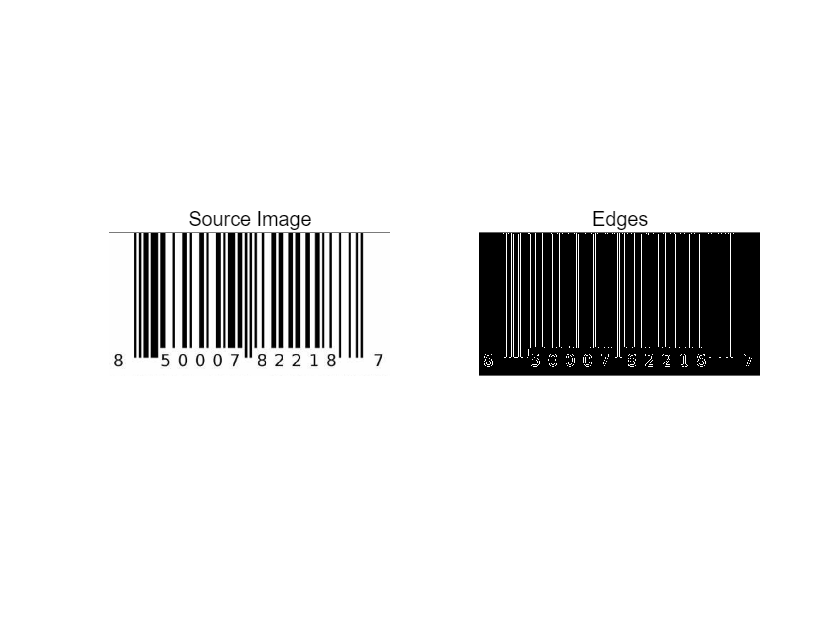


I = imread(imagePaths{3});
if isempty(I)
    error('Error reading the image.');
end

% Convert to grayscale if necessary
if size(I, 3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end
% Detect edges using the Canny edge detector
I_edge = edge(I_gray, 'canny', [0.1 0.2]);

% Display the original and edge-detected images
figure;
subplot(1, 2, 1); imshow(I); title('Source Image');
subplot(1, 2, 2); imshow(I_edge); title('Edges');

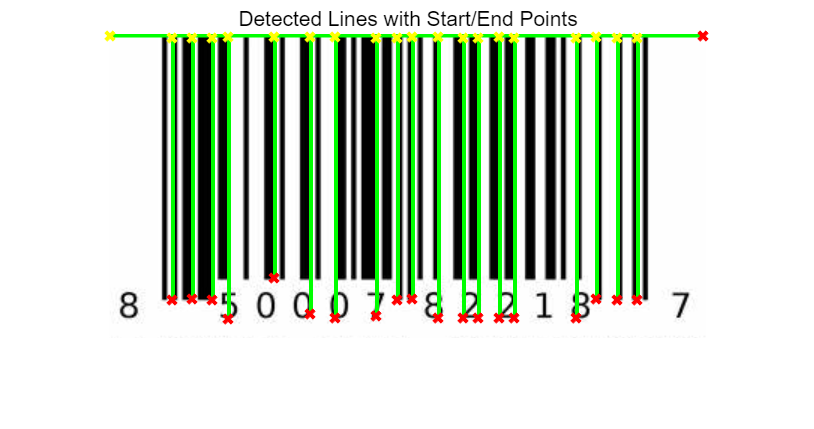

% Compute the Hough transform
[H, theta, rho] = hough(I_edge);

% Find peaks in the Hough transform accumulator
peaks = houghpeaks(H, 20, 'Threshold', 25);

% Extract lines using the Hough lines function
lines = houghlines(I_edge, theta, rho, peaks);
% Create a copy of the original image to draw lines on
I_lines = I;
% Plot the detected lines
figure;
imshow(I_lines); hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:, 1), xy(:, 2), 'LineWidth', 2, 'Color', 'green');
    
    % Mark the start and end points
    plot(xy(1, 1), xy(1, 2), 'x', 'LineWidth', 2, 'Color', 'yellow');
    plot(xy(2, 1), xy(2, 2), 'x', 'LineWidth', 2, 'Color', 'red');
end
title('Detected Lines with Start/End Points');
hold off;




I = imread(imagePaths{1});
if isempty(I)
    error('Error reading the image.');
end

% Convert to grayscale if necessary
if size(I, 3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end
% Detect edges using the Canny edge detector
I_edge = edge(I_gray, 'canny', [0.2 0.5]);

% Display the original and edge-detected images
figure;
subplot(1, 2, 1); imshow(I); title('Source Image');
subplot(1, 2, 2); imshow(I_edge); title('Edges');

% Compute the Hough transform
[H, theta, rho] = hough(I_edge);

% Find peaks in the Hough transform accumulator
peaks = houghpeaks(H, 20, 'Threshold', 25);

% Extract lines using the Hough lines function
lines = houghlines(I_edge, theta, rho, peaks);
% Create a copy of the original image to draw lines on
I_lines = I;
% Plot the detected lines
figure;
imshow(I_lines); hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:, 1), xy(:, 2), 'LineWidth', 2, 'Color', 'green');
    
    % Mark the start and end points
    plot(xy(1, 1), xy(1, 2), 'x', 'LineWidth', 2, 'Color', 'yellow');
    plot(xy(2, 1), xy(2, 2), 'x', 'LineWidth', 2, 'Color', 'red');
end
title('Detected Lines with Start/End Points');
hold off;

### **1.2** **Probabilistic Hough Transform for Lines**

Let's repeat again the same steps and calculate Probabilistic Hough Transform for Lines. 

The steps related to image preframing and boundary (edge) selection remain the same.

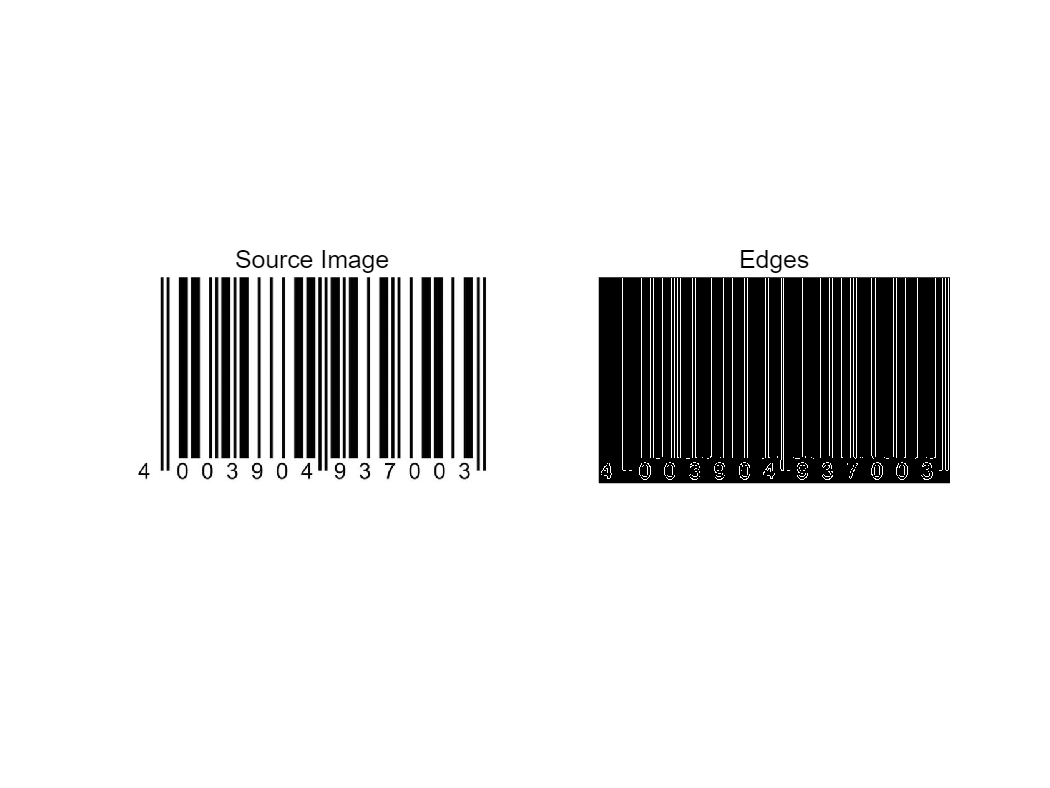

clear all;
clc; 

% Read an image
I = imread('images/pic1.png');
if isempty(I)
    error('Error reading the image.');
end

% Convert to grayscale if necessary
if size(I, 3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

% Detect edges using the Canny edge detector
I_edge = edge(I_gray, 'canny');

% Display the original and edge-detected images
figure;
subplot(1, 2, 1); imshow(I); title('Source Image');
subplot(1, 2, 2); imshow(I_edge); title('Edges');

Next, compute the Hough transform and identify peaks (again, in the same way, like it was done):

% Compute the Hough transform
[H, theta, rho] = hough(I_edge);

% Find peaks in the Hough transform accumulator
peaks = houghpeaks(H, 50, 'Threshold', 50);

Now, to implement the probabilistic variant, we will use the function `lines = houghlines(I_edge, theta, rho, peaks, Name, Value)`. This is the same function that was used earlier, but now we have added name-value pair arguments to control various aspects of the line extraction.

% Extract line segments with smaller FillGap and MinLength for shorter lines
lines_p = houghlines(I_edge, theta, rho, peaks, 'FillGap', 5, 'MinLength', 50);

Here:

- `FillGap` is a parameter that specifies the maximum distance (in pixels) between two line segments that can be combined into a single line.

- `MinLength` is the minimum length (in pixels) of the detected line. Lines shorter than this value are ignored.

Finally, plot the detected lines on the original image:

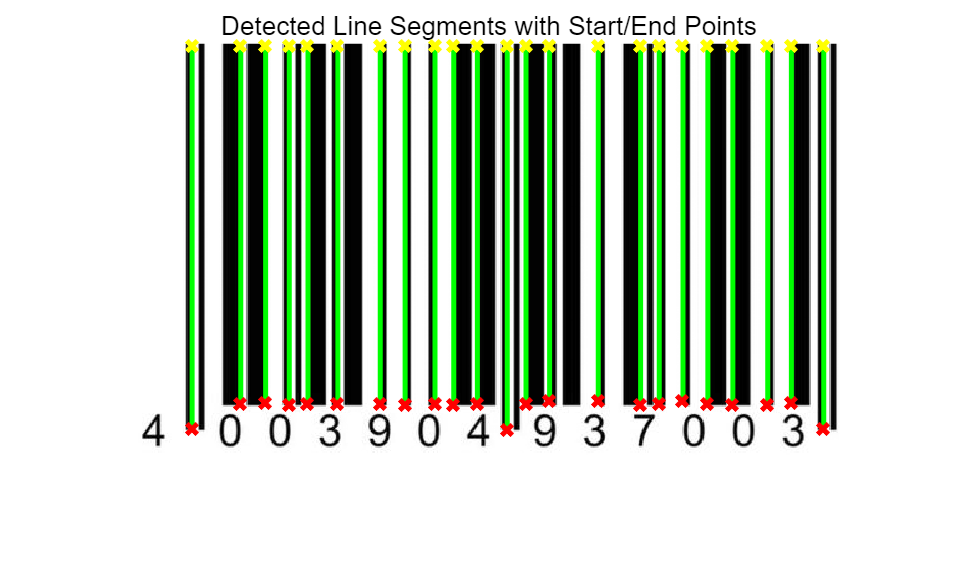

% Plot the detected line segments
I_lines_p = I;
figure;
imshow(I_lines_p); hold on;
for k = 1:length(lines_p)
    xy = [lines_p(k).point1; lines_p(k).point2];
    plot(xy(:, 1), xy(:, 2), 'LineWidth', 2, 'Color', 'green');
    
    % Mark the start and end points
    plot(xy(1, 1), xy(1, 2), 'x', 'LineWidth', 2, 'Color', 'yellow');
    plot(xy(2, 1), xy(2, 2), 'x', 'LineWidth', 2, 'Color', 'red');
end
title('Detected Line Segments with Start/End Points');
hold off;

Let's calculate and display statistical information:

% Calculate the number of lines, shortest, and longest lengths
num_lines_p = length(lines_p);
line_lengths_p = arrayfun(@(x) norm(x.point1 - x.point2), lines_p);
shortest_length_p = min(line_lengths_p);
longest_length_p = max(line_lengths_p);

% Display the results
fprintf('Found %d line segments.\n', num_lines_p);

Found 23 line segments.


fprintf('The shortest line segment length is %.2f pixels.\n', shortest_length_p);

The shortest line segment length is 285.00 pixels.


fprintf('The longest line segment length is %.2f pixels.\n', longest_length_p);

The longest line segment length is 308.00 pixels.


# ***Self-work***

Take **three** arbitrary images and execute the classic Hough transform. Display the found lines and print their number. 

*Notes. You may have to change the Hough transform parameters to match your images.*

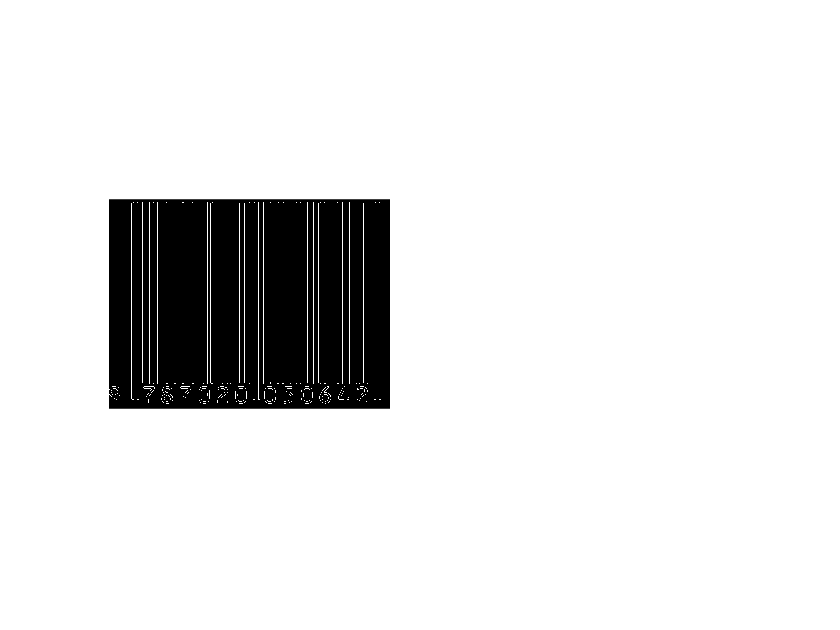

数组索引必须为正整数或逻辑值。

% TODO Place your solution here

imagePaths = {'images/pic4.png', 'images/pic2.png', 'images/pic3.png'};
% Using same images as before
I = imread(imagePaths{1});

if size(I, 3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

I_edge = edge(I_gray, 'canny', [0.2 0.5]);

[H, theta, rho] = hough(I_edge);
peaks = houghpeaks(H, 50, 'Threshold', 50);

% Probabilistic version with different parameters
lines_p = houghlines(I_edge, theta, rho, peaks, 'FillGap', 5, 'MinLength', 50);

figure;
subplot(1,2,1); imshow(I_edge); title(['Edges - ', imagePaths{i}]);

subplot(1,2,2); imshow(I); hold on;

for k = 1:length(lines_p)
    xy = [lines_p(k).point1; lines_p(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
    plot(xy(1,1), xy(1,2), 'x', 'LineWidth', 2, 'Color', 'yellow');
    plot(xy(2,1), xy(2,2), 'x', 'LineWidth', 2, 'Color', 'red');
end
title(['Probabilistic Hough - ', imagePaths{i}]);
hold off;

num_lines_p = length(lines_p);
lengths_p = arrayfun(@(x) norm(x.point1 - x.point2), lines_p);
shortest_p = min(lengths_p);
longest_p = max(lengths_p);

fprintf('Image %s (Probabilistic):\n', imagePaths{i});
fprintf('  Found %d lines\n', num_lines_p);
fprintf('  Shortest line: %.2f pixels\n', shortest_p);
fprintf('  Longest line: %.2f pixels\n\n', longest_p);


I = imread(imagePaths{2});

if size(I, 3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

I_edge = edge(I_gray, 'canny', [0.2 0.5]);

[H, theta, rho] = hough(I_edge);
peaks = houghpeaks(H, 50, 'Threshold', 50);

% Probabilistic version with different parameters
lines_p = houghlines(I_edge, theta, rho, peaks, 'FillGap', 5, 'MinLength', 50);

figure;
subplot(1,2,1); imshow(I_edge); title(['Edges - ', imagePaths{i}]);
subplot(1,2,2); imshow(I); hold on;

for k = 1:length(lines_p)
    xy = [lines_p(k).point1; lines_p(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
    plot(xy(1,1), xy(1,2), 'x', 'LineWidth', 2, 'Color', 'yellow');
    plot(xy(2,1), xy(2,2), 'x', 'LineWidth', 2, 'Color', 'red');
end
title(['Probabilistic Hough - ', imagePaths{i}]);
hold off;

num_lines_p = length(lines_p);
lengths_p = arrayfun(@(x) norm(x.point1 - x.point2), lines_p);
shortest_p = min(lengths_p);
longest_p = max(lengths_p);

fprintf('Image %s (Probabilistic):\n', imagePaths{i});
fprintf('  Found %d lines\n', num_lines_p);
fprintf('  Shortest line: %.2f pixels\n', shortest_p);
fprintf('  Longest line: %.2f pixels\n\n', longest_p);



I = imread(imagePaths{3});

if size(I, 3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

I_edge = edge(I_gray, 'canny', [0.2 0.5]);

[H, theta, rho] = hough(I_edge);
peaks = houghpeaks(H, 50, 'Threshold', 50);

% Probabilistic version with different parameters
lines_p = houghlines(I_edge, theta, rho, peaks, 'FillGap', 5, 'MinLength', 50);

figure;
subplot(1,2,1); imshow(I_edge); title(['Edges - ', imagePaths{i}]);
subplot(1,2,2); imshow(I); hold on;

for k = 1:length(lines_p)
    xy = [lines_p(k).point1; lines_p(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
    plot(xy(1,1), xy(1,2), 'x', 'LineWidth', 2, 'Color', 'yellow');
    plot(xy(2,1), xy(2,2), 'x', 'LineWidth', 2, 'Color', 'red');
end
title(['Probabilistic Hough - ', imagePaths{i}]);
hold off;

num_lines_p = length(lines_p);
lengths_p = arrayfun(@(x) norm(x.point1 - x.point2), lines_p);
shortest_p = min(lengths_p);
longest_p = max(lengths_p);

fprintf('Image %s (Probabilistic):\n', imagePaths{i});
fprintf('  Found %d lines\n', num_lines_p);
fprintf('  Shortest line: %.2f pixels\n', shortest_p);
fprintf('  Longest line: %.2f pixels\n\n', longest_p);


### **1.3 Classic Hough Transform for Lines (another approach)**

Let some image be given. Let select the contours using the Canny algorithm and apply the Hough transform using the `hough()` MATLAB function. 

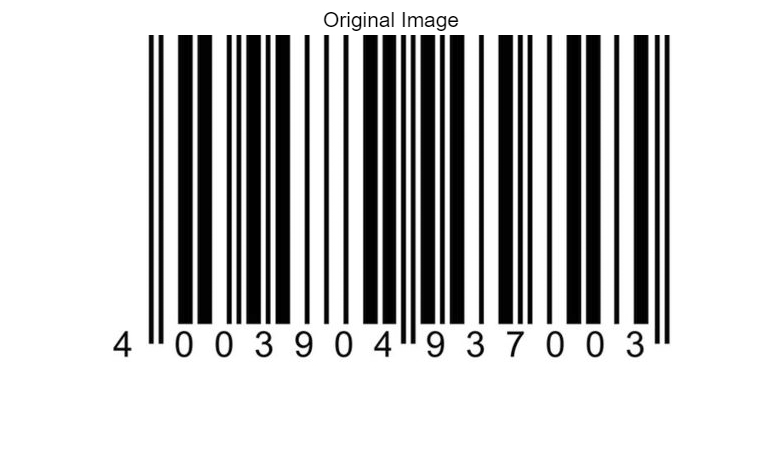

clc;
clear all;

I = rgb2gray(imread('images/pic1.png'));

figure;
imshow(I);
title('Original Image');

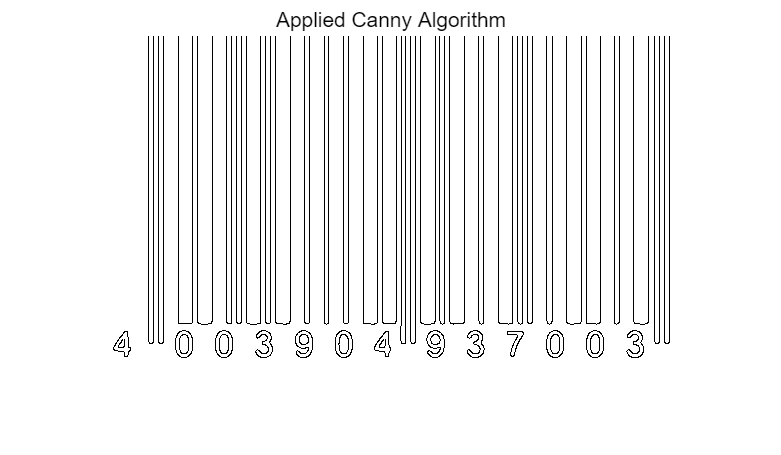

Iedge = edge(I, 'Canny');

figure;
imshow(~Iedge);
title('Applied Canny Algorithm');

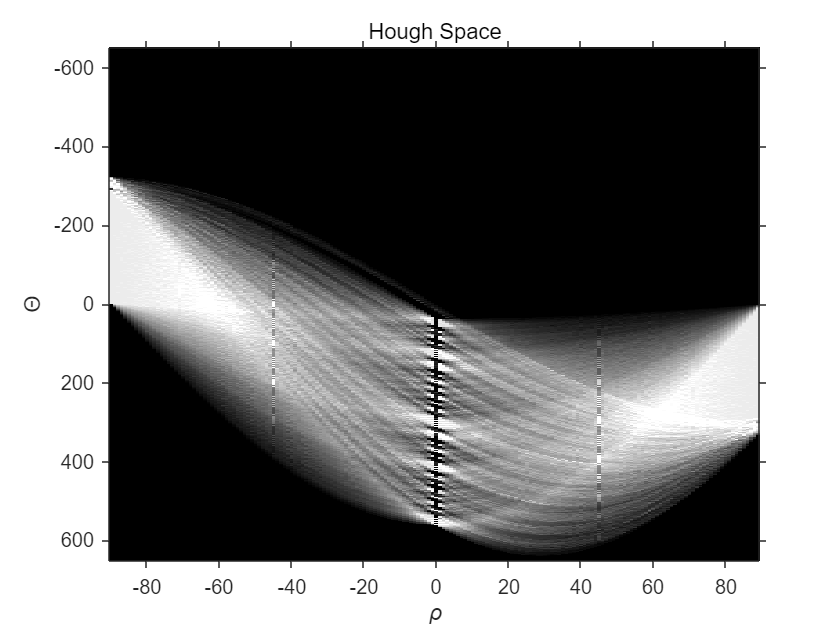

[H,Theta,rho] = hough(Iedge);

figure, imshow(imadjust(mat2gray(H)),[],'YData',rho,'XData',Theta, 'InitialMagnification','fit');
xlabel('\rho'), ylabel('\Theta')
title('Hough Space');
axis on, axis normal, hold on

Let’s calculate the peaks using the `houghpeaks()` function in the Hough space and plot them on the resulting image of the response functions:

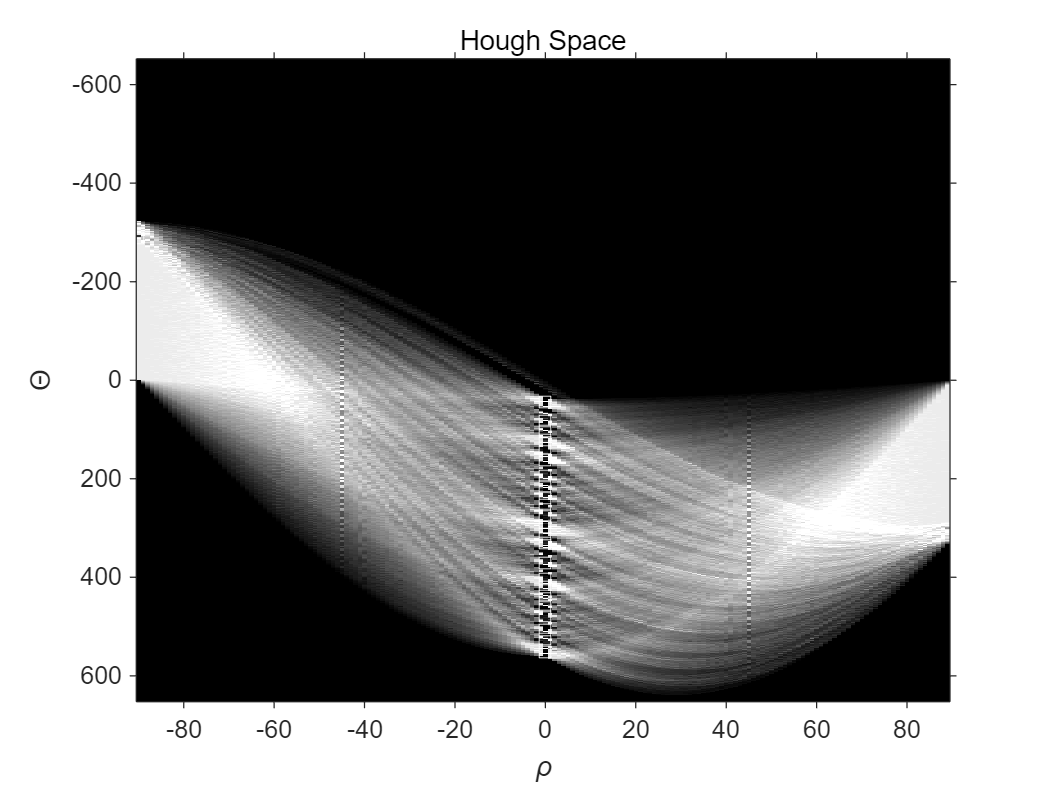

peaks = houghpeaks(H,100,'threshold',ceil(0.5 * max(H(:))));
x = Theta(peaks(:,2));
y = rho(peaks(:,1));
plot(x,y,'s','color','white');

Based on the peaks, we determine the straight lines using the `houghlines()` MATLAB function and plot them on the original image:

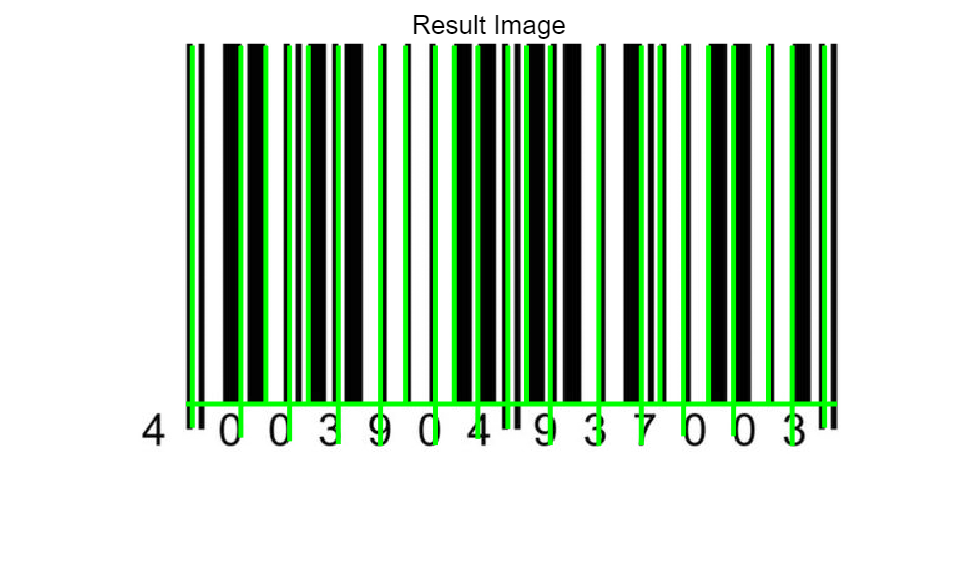

lines = houghlines(Iedge,Theta,rho,peaks);
%lines = houghlines(Iedge,Theta,rho,peaks, 'FillGap',5,'MinLength',10);
figure;
imshow(I)
title('Result Image');
hold on
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
end

disp(['Number of found lines: ', num2str(length(lines))]);

Number of found lines: 24


# ***Self-work***

Take **three** arbitrary images and execute the classic Hough transform. Display the found lines and print their number. 

***Notes.**** You may have to change the Hough transform parameters to match your images.*

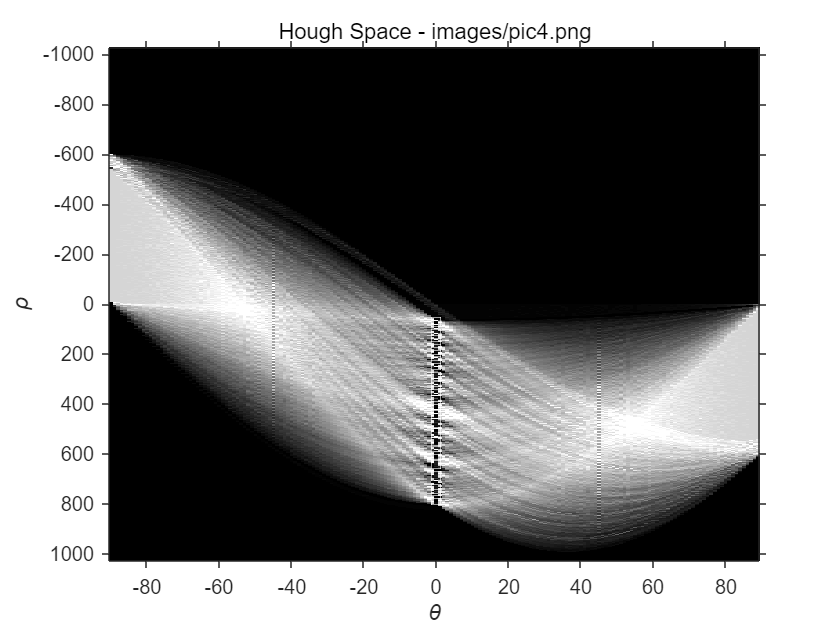

% TODO Place your solution here
imagePaths = {'images/pic4.png', 'images/pic2.png', 'images/pic3.png'};

i = 1;
I = imread(imagePaths{1});
I_gray = rgb2gray(I);

% Edge detection
Iedge = edge(I_gray, 'Canny');

% Hough transform
[H,Theta,rho] = hough(Iedge);

% Display Hough space
figure;
imshow(imadjust(mat2gray(H)),[],'YData',rho,'XData',Theta,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
title(['Hough Space - ', imagePaths{i}]);
axis on, axis normal, hold on;

% Find peaks
peaks = houghpeaks(H,100,'threshold',ceil(0.5*max(H(:))));
x = Theta(peaks(:,2));
y = rho(peaks(:,1));
plot(x,y,'s','color','white');

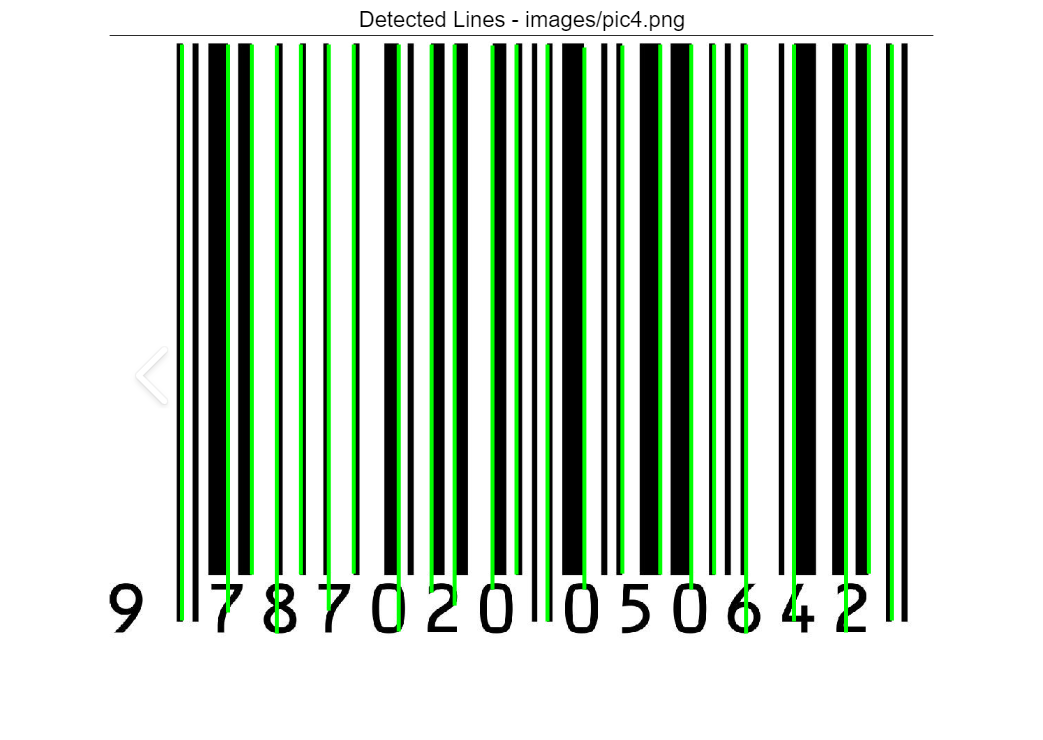


% Extract lines
lines = houghlines(Iedge,Theta,rho,peaks);

% Display lines on original image
figure;
imshow(I);
title(['Detected Lines - ', imagePaths{i}]);
hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth',2,'Color','green');
end
hold off;


fprintf('Image %s (Alternative): Found %d lines\n\n', imagePaths{i}, length(lines));

Image images/pic4.png (Alternative): Found 23 lines



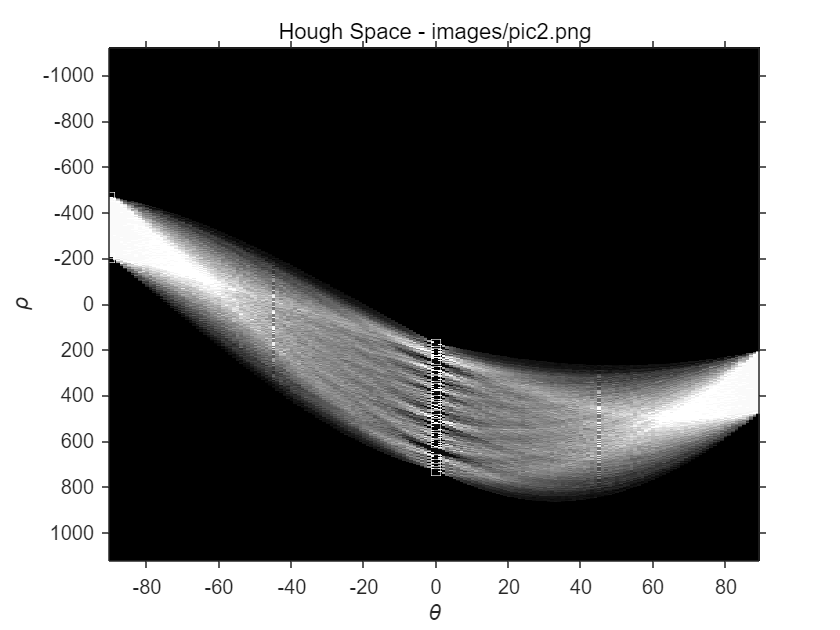


i = 2;
I = imread(imagePaths{2});
I_gray = im2gray(I);

% Edge detection
Iedge = edge(I_gray, 'Canny');

% Hough transform
[H,Theta,rho] = hough(Iedge);

% Display Hough space
figure;
imshow(imadjust(mat2gray(H)),[],'YData',rho,'XData',Theta,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
title(['Hough Space - ', imagePaths{i}]);
axis on, axis normal, hold on;

% Find peaks
peaks = houghpeaks(H,100,'threshold',ceil(0.5*max(H(:))));
x = Theta(peaks(:,2));
y = rho(peaks(:,1));
plot(x,y,'s','color','white');

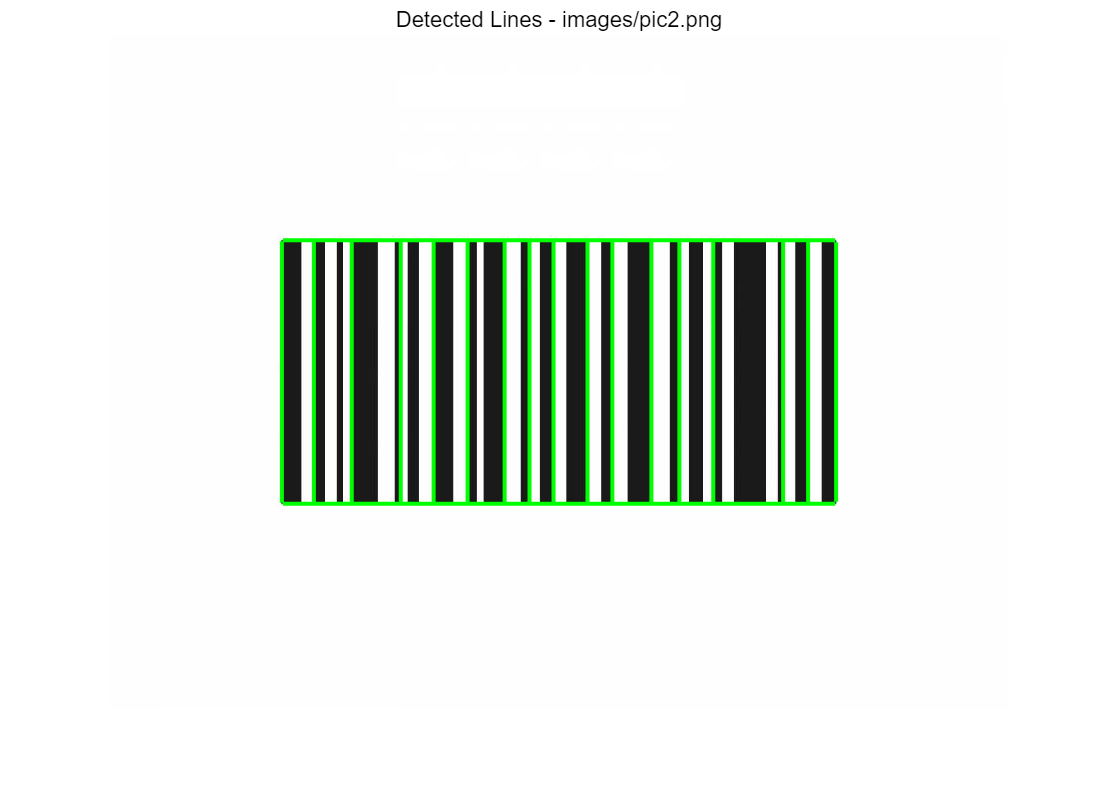


% Extract lines
lines = houghlines(Iedge,Theta,rho,peaks);

% Display lines on original image
figure;
imshow(I);
title(['Detected Lines - ', imagePaths{i}]);
hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth',2,'Color','green');
end
hold off;


fprintf('Image %s (Alternative): Found %d lines\n\n', imagePaths{i}, length(lines));

Image images/pic2.png (Alternative): Found 19 lines



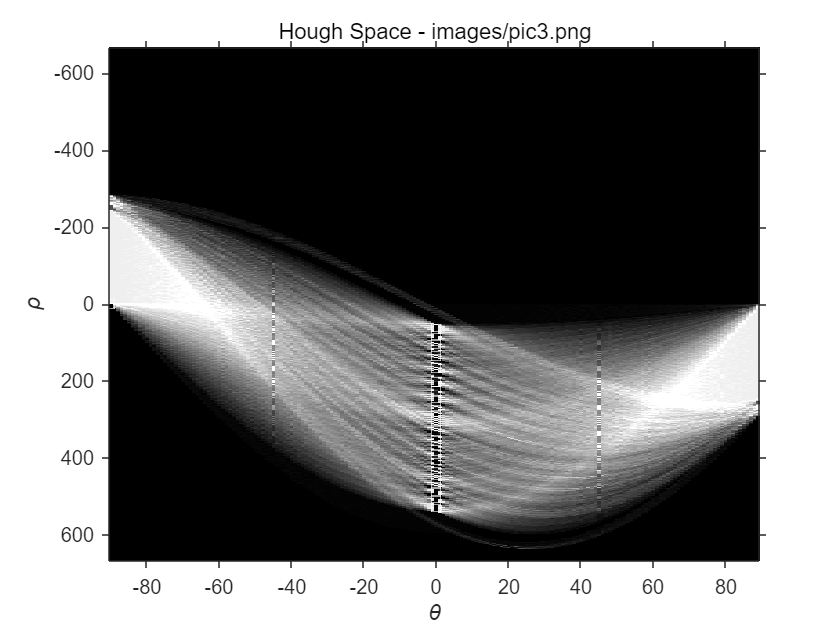



I = imread(imagePaths{3});

i = 3;
I_gray = rgb2gray(I);

% Edge detection
Iedge = edge(I_gray, 'Canny');

% Hough transform
[H,Theta,rho] = hough(Iedge);

% Display Hough space
figure;
imshow(imadjust(mat2gray(H)),[],'YData',rho,'XData',Theta,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
title(['Hough Space - ', imagePaths{i}]);
axis on, axis normal, hold on;

% Find peaks
peaks = houghpeaks(H,100,'threshold',ceil(0.5*max(H(:))));
x = Theta(peaks(:,2));
y = rho(peaks(:,1));
plot(x,y,'s','color','white');

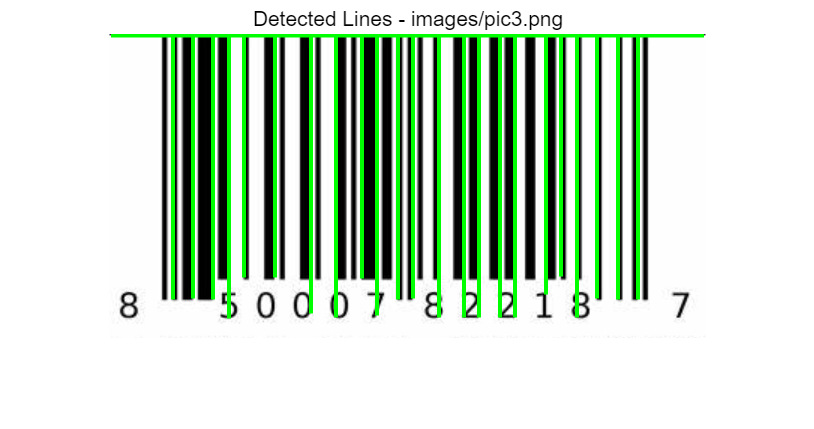


% Extract lines
lines = houghlines(Iedge,Theta,rho,peaks);

% Display lines on original image
figure;
imshow(I);
title(['Detected Lines - ', imagePaths{i}]);
hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth',2,'Color','green');
end
hold off;


fprintf('Image %s (Alternative): Found %d lines\n\n', imagePaths{i}, length(lines));

Image images/pic3.png (Alternative): Found 24 lines



### **1.4 Probabilistic Hough Transform for Lines (another approach)**

Let's repeat again the same steps and calculate Probabilistic Hough Transform for Lines.

clear all;
clc;

I = imread('images/pic1.png');
if size(I,3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

figure;
imshow(I);
title('Original Image');

Let's apply the Canny algorithm to the grayscale representation using `edge()` function and dispay it:

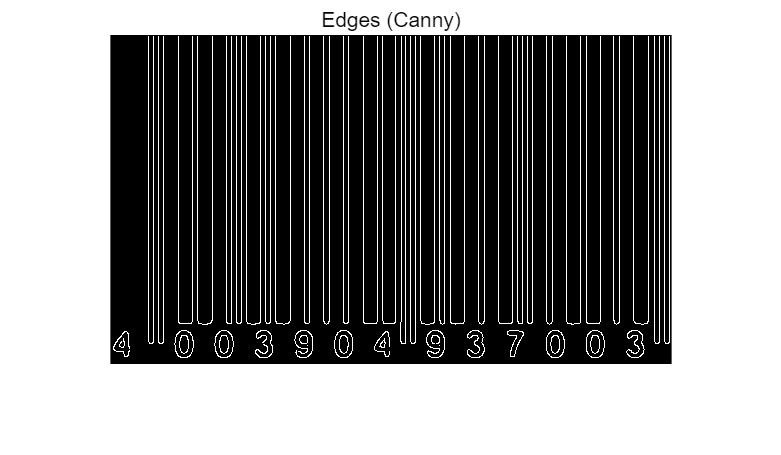

BW = edge(I_gray, 'canny', [0.1 0.2], 2);

figure;
imshow(BW);
title('Edges (Canny)');

Let’s calculate the peaks using the `houghpeaks()` function in the Hough space and plot them on the resulting image of the response functions:

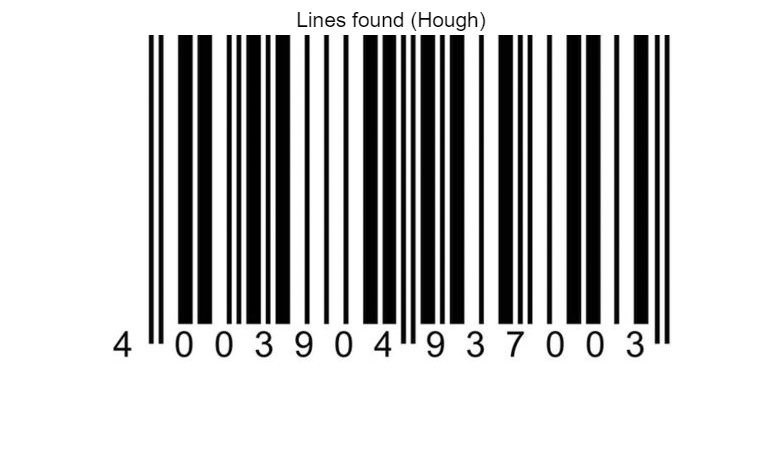

[H,theta,rho] = hough(BW);

P = houghpeaks(H, 30, 'threshold', ceil(0.5 * max(H(:))));

lines = houghlines(BW, theta, rho, P, 'FillGap', 10, 'MinLength', 50);      

figure;
imshow(I), hold on;
title('Lines found (Hough)');

Let's calculate and display statistical information:

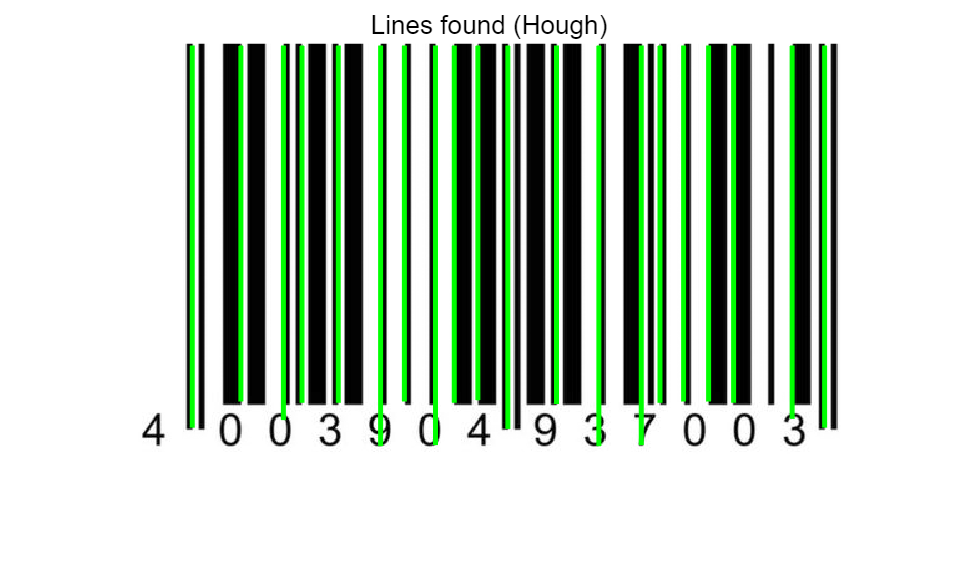

for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
end

fprintf('Lines found: %d\n', length(lines));

Lines found: 20


# ***Self-work***

Take **three** arbitrary images and execute **Probabilistic Hough Transform for Lines (another approach):**

- Display the Hough space, like it was done in **section 1.3.**

- Dispaly the found lines and print their number.

***Notes.**** You may have to change the Hough transform parameters to match your images.*

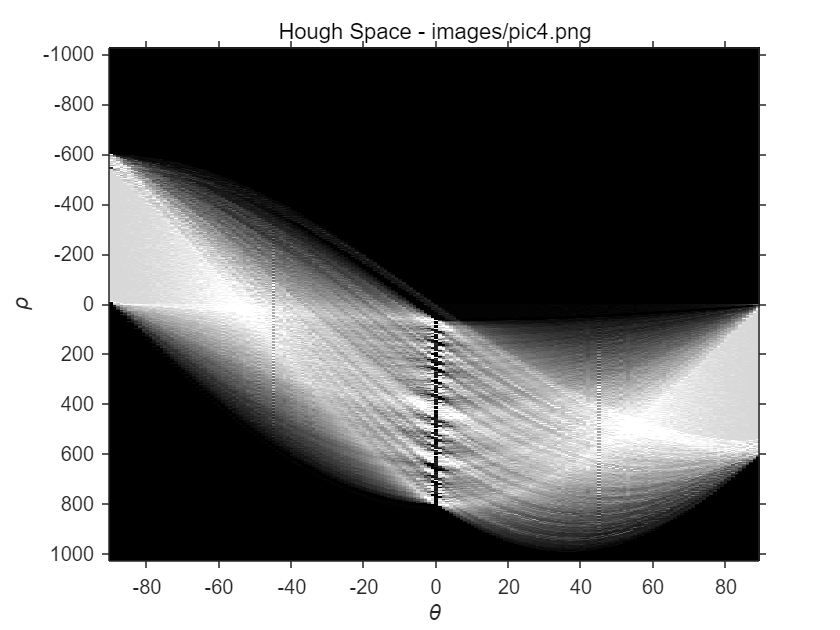

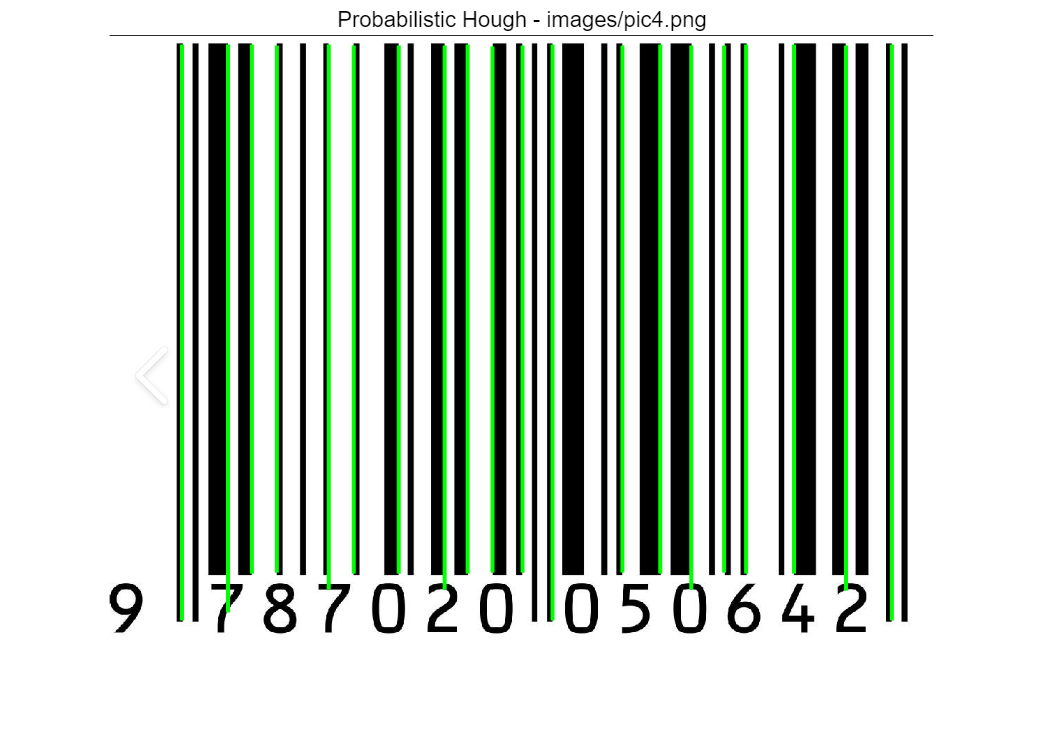

Image images/pic4.png (Prob. Alternative): Found 20 lines



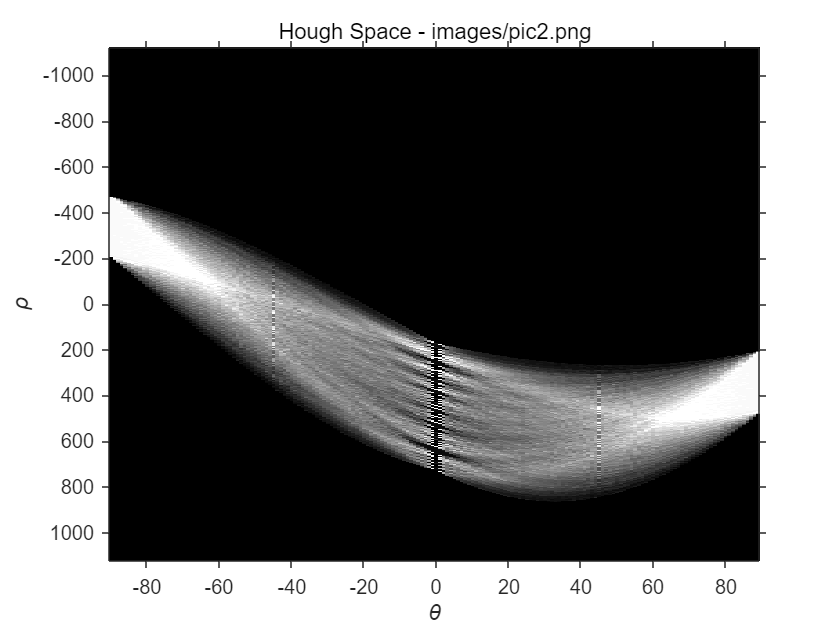

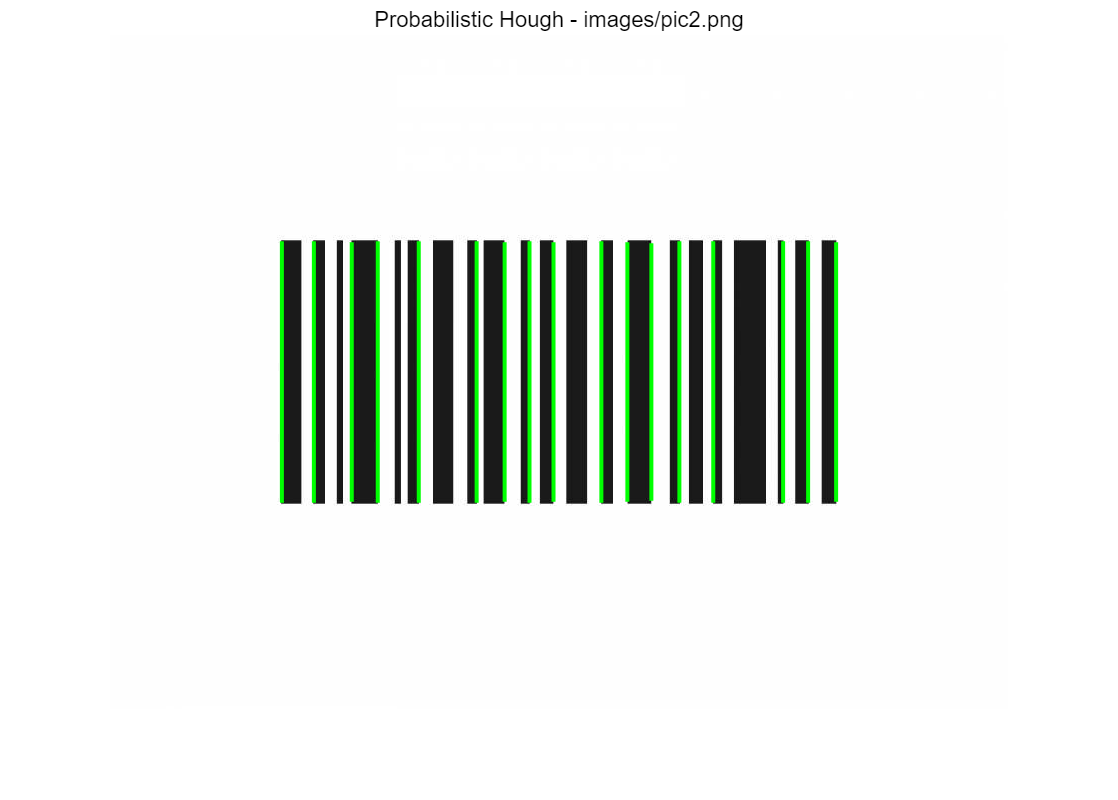

Image images/pic2.png (Prob. Alternative): Found 17 lines



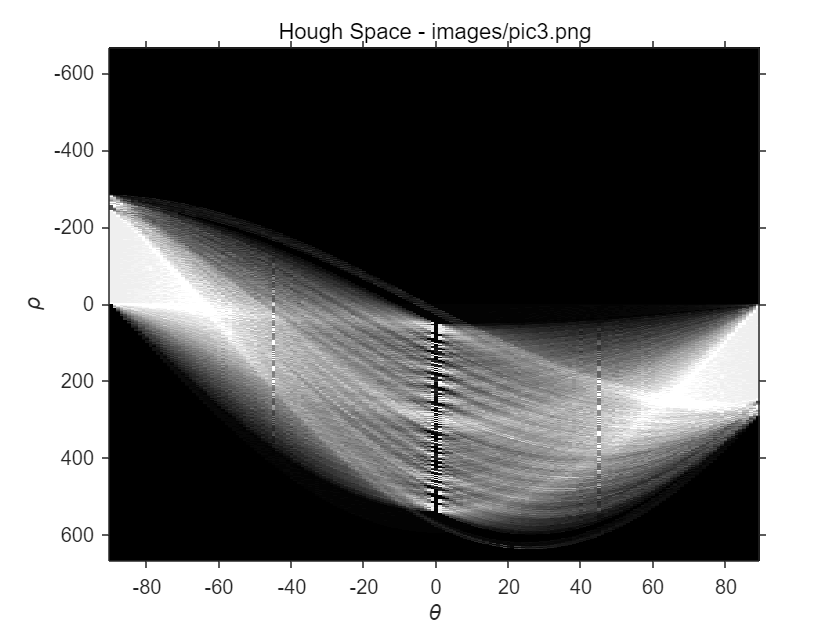

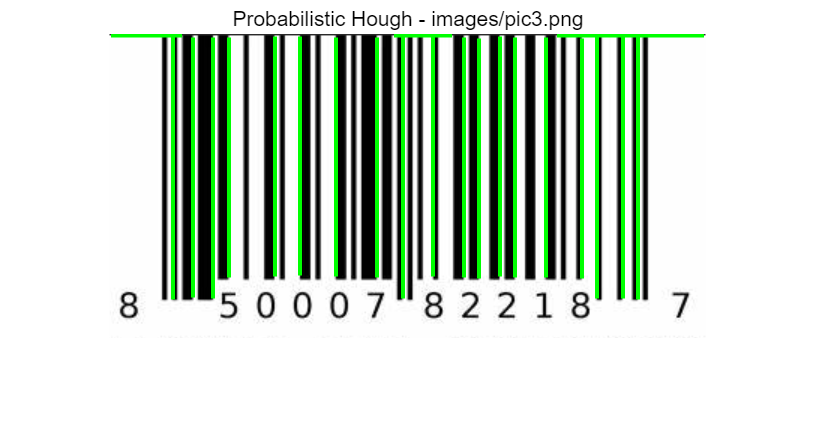

Image images/pic3.png (Prob. Alternative): Found 22 lines



% TODO Place your solution here

imagePaths = {'images/pic4.png', 'images/pic2.png', 'images/pic3.png'};
for i = 1:length(imagePaths)
    I = imread(imagePaths{i});
    if size(I,3) == 3
        I_gray = rgb2gray(I);
    else
        I_gray = I;
    end
    
    % Edge detection with adjusted parameters
    BW = edge(I_gray, 'canny', [0.1 0.2], 2);
    
    % Hough transform and display space
    [H,theta,rho] = hough(BW);
    figure;
    imshow(imadjust(mat2gray(H)),[],'YData',rho,'XData',theta,'InitialMagnification','fit');
    xlabel('\theta'), ylabel('\rho');
    title(['Hough Space - ', imagePaths{i}]);
    axis on, axis normal;
    
    % Find peaks and lines
    P = houghpeaks(H, 20, 'threshold', ceil(0.3*max(H(:))));
    lines = houghlines(BW, theta, rho, P, 'FillGap', 10, 'MinLength', 50);
    
    % Display results
    figure;
    imshow(I), hold on;
    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2];
        plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
    end
    title(['Probabilistic Hough - ', imagePaths{i}]);
    hold off;
    
    fprintf('Image %s (Prob. Alternative): Found %d lines\n\n', imagePaths{i}, length(lines));
end

## Task 2. Search for Circles

*Take three arbitrary images containing circles. Search for circles of a known radius range using the Hough transform. Plot the found circles on the original image and print the number of found circles.*

### 2.1 Hough Transform for Circles

In MATLAB, the Hough transform for circles can be implemented using the `imfindcircles()` function. This function detects circles in a grayscale or binary image using a circular Hough transform (CHT). The function returns the centers and radii of the detected circles.

Basic parameters of the `imfindcircles()` function:

- `ObjectPolarity` — `bright` (looking for light circles on a dark background) or `dark` (vice versa);

- `Method` — `PhaseCode` (fast) or `TwoStage` (accurate);

- `Sensitivity` — from 0 to 1 (the higher it is, the more false alarms);

- `EdgeThreshold` — threshold for borders (0-1, the higher, the stricter).

Firstly, let's preprocess the image to detect edges using the Canny edge detector:

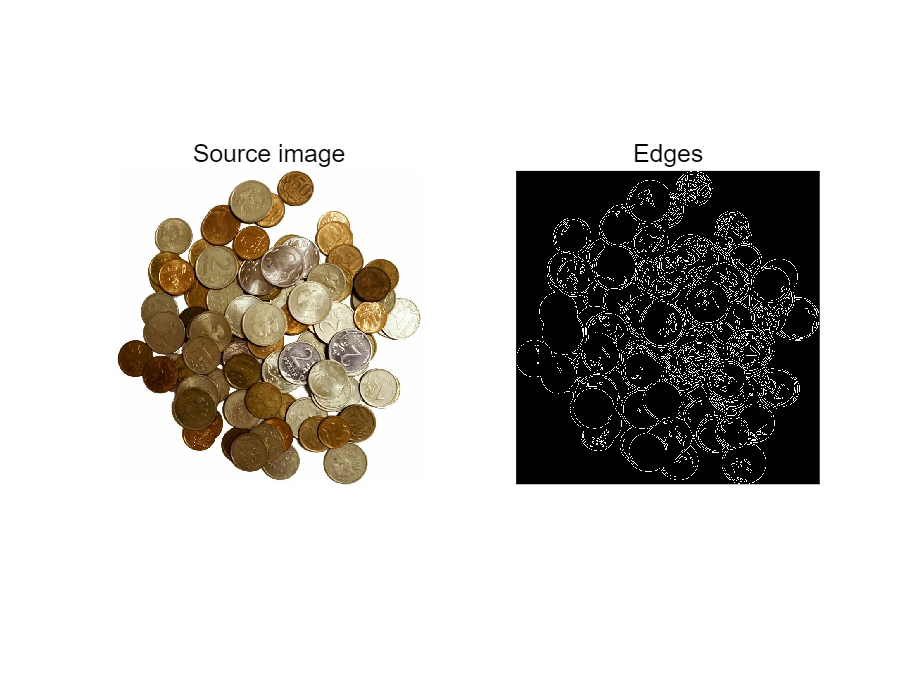

clear all;
clc;

fn = 'images/coins.png';
I2 = imread(fn);
if isempty(I2)
    error('Error reading file "%s"', fn);
end

% Pre-processing with Canny algorithm and display it
I2edge = edge(rgb2gray(I2), 'Canny', [0 50]/255);

figure;
subplot(1,2,1); imshow(I2); title('Source image');
subplot(1,2,2); imshow(I2edge); title('Edges');

Let's apply `imfindcircles()` function to detect all circles with radiuses in a range between 30 and 70 pixels:

% Set radius range (min and max)
radiusRange = [30, 70]; 

[centers, radii, metric] = imfindcircles(I2, radiusRange, ...
    'ObjectPolarity', 'bright', ...
    'Method', 'TwoStage', ...
    'Sensitivity', 0.9, ...
    'EdgeThreshold', 0.2);

I2out = I2;
I2circles = zeros(size(I2));

Let's display all found circles:

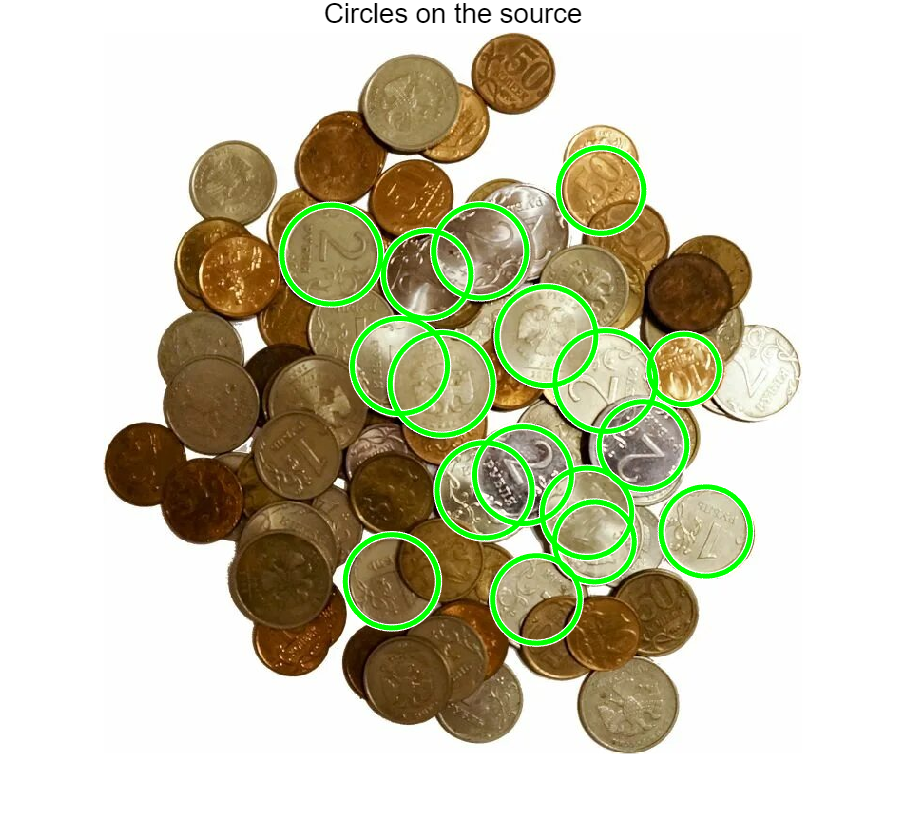

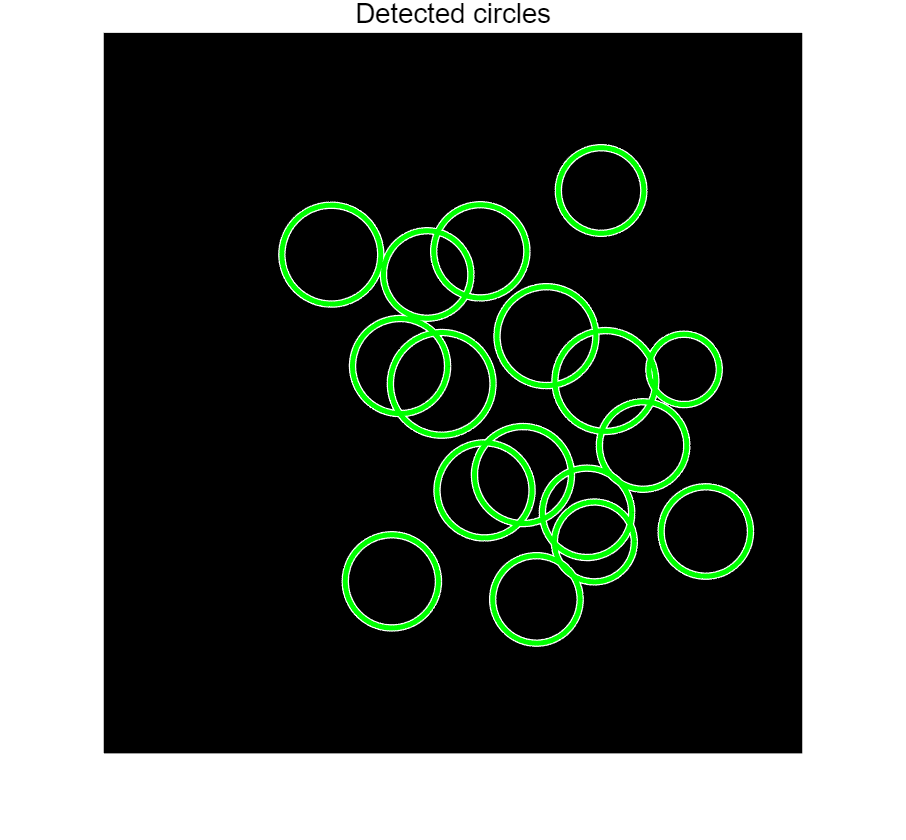

Found 17 circles


if ~isempty(centers)
   
    figure;
    imshow(I2out);
    viscircles(centers, radii, 'Color', 'green');
    title('Circles on the source');
    
    figure;
    imshow(I2circles);
    viscircles(centers, radii, 'Color', 'green');
    title('Detected circles');
    
    fprintf('Found %d circles\n', size(centers, 1));
else
    disp('No circles found');
end

# ***Self-work***

Take **three **arbitrary images and execute the Hough transform for circles. Display the found circles and print their number.

*Notes.* *You may have to change the *`imfindcircles()` *function parameters to match your images.*

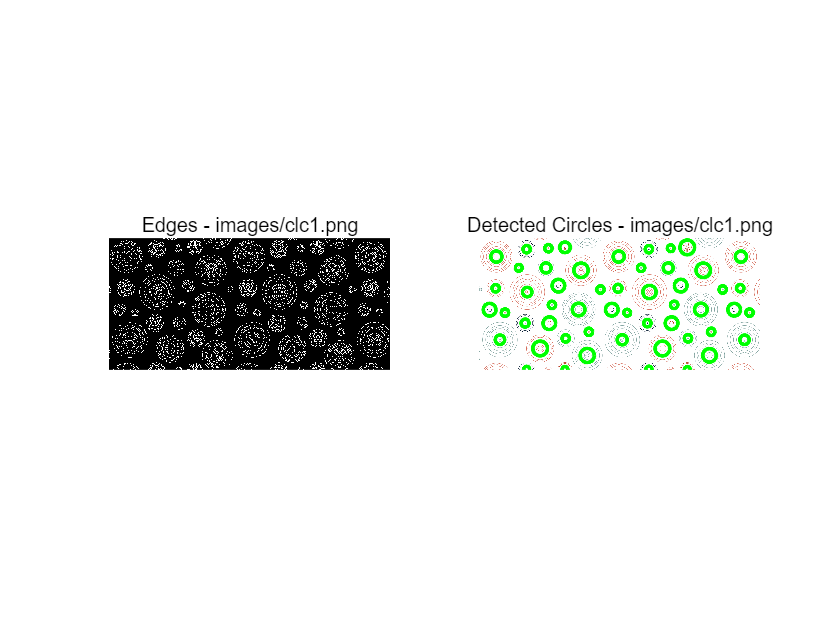

Image images/clc1.png: Found 53 circles



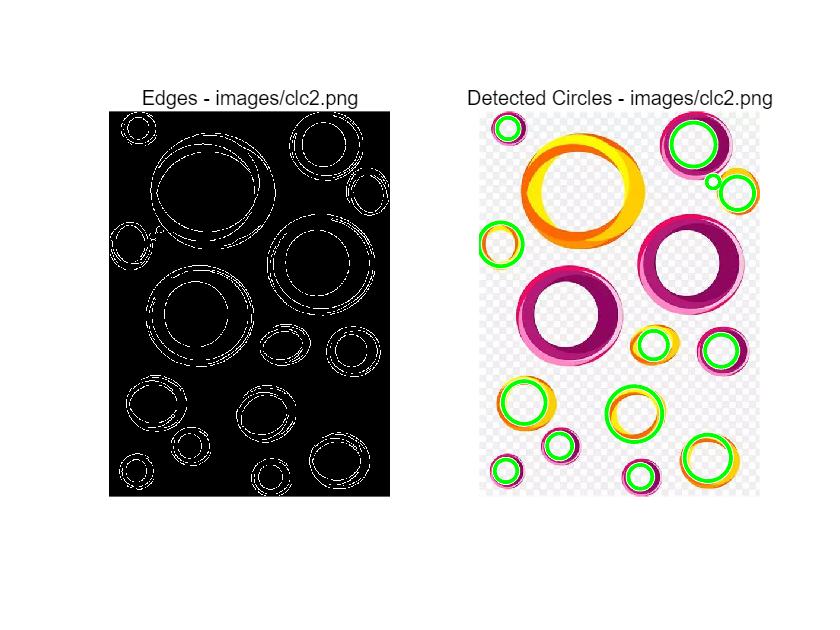

Image images/clc2.png: Found 13 circles



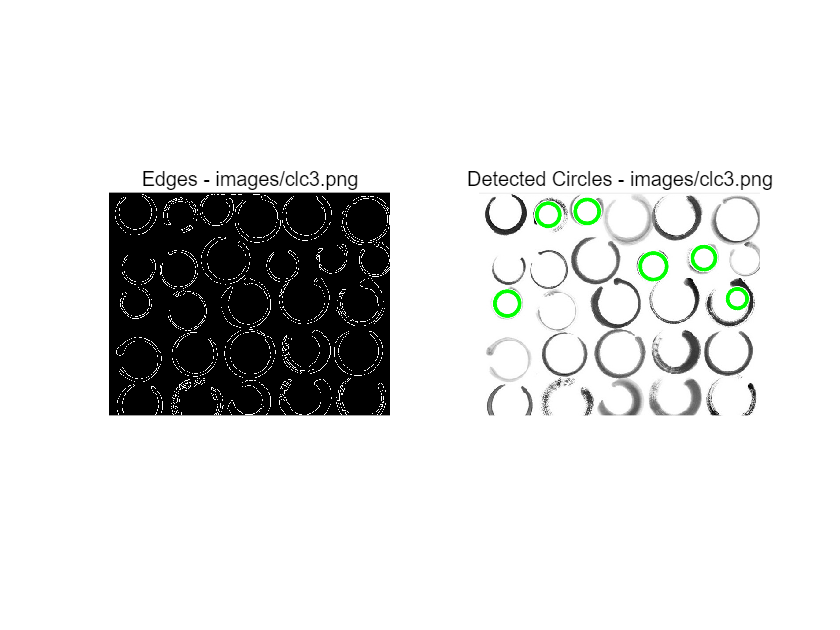

Image images/clc3.png: Found 6 circles



% TODO Place your solution here
circleImages = {'images/clc1.png', 'images/clc2.png', 'images/clc3.png'};

for i = 1:length(circleImages)
    I = imread(circleImages{i});
    
    % Edge detection
    Iedge = edge(rgb2gray(I), 'Canny', [0 50]/255);
    
    % Find circles with appropriate radius ranges
    if i == 1 % coins
        radiusRange = [20 50];
    elseif i == 2 % balls
        radiusRange = [6 50];
    else % target
        radiusRange = [15 30];
    end
    
    [centers, radii, metric] = imfindcircles(I, radiusRange, ...
        'ObjectPolarity', 'bright', ...
        'Method', 'TwoStage', ...
        'Sensitivity', 0.9, ...
        'EdgeThreshold', 0.2);
    
    % Display results
    figure;
    subplot(1,2,1); imshow(Iedge); title(['Edges - ', circleImages{i}]);
    subplot(1,2,2); imshow(I); 
    viscircles(centers, radii, 'Color', 'green');
    title(['Detected Circles - ', circleImages{i}]);
    
    fprintf('Image %s: Found %d circles\n\n', circleImages{i}, size(centers,1));
end

## **Task 3. Implement the classic Hough transform algorithms for lines by yourself**

# ***Self-work. Optional***

**Compare your implementation results with ones obtained in the first task of this practical assignment. **To implement the Hough Transform for straight lines you must allocate an accumulator matrix manually and implement the classic algorithm for the Hough transform to fill the accumulator matrix. The pseudocode for this process is as follows:

%For each point in the source space (x, y)
% For theta = 0 to 180
%    rho = x * cos(theta) + y * sin(theta);
%    H(theta, rho) = H(theta, rho) + 1;
%  end
%end

***Optional: *****For this optional task you may earn 1 extra point. **

After the accumulator matrix is filled, you should identify the maxima. The simplest way to achieve this is by applying a thresholding method, which you learned in the previous class.

***Notes:***

- Performance Considerations: A MATLAB implementation of this algorithm can be computationally expensive, especially for high-resolution images. To optimize performance, consider using a low-resolution input image.

- Edge Detection: Don’t forget to apply the Canny edge detection algorithm before performing the Hough transform. This step ensures that only edge points are considered, reducing noise and improving accuracy.

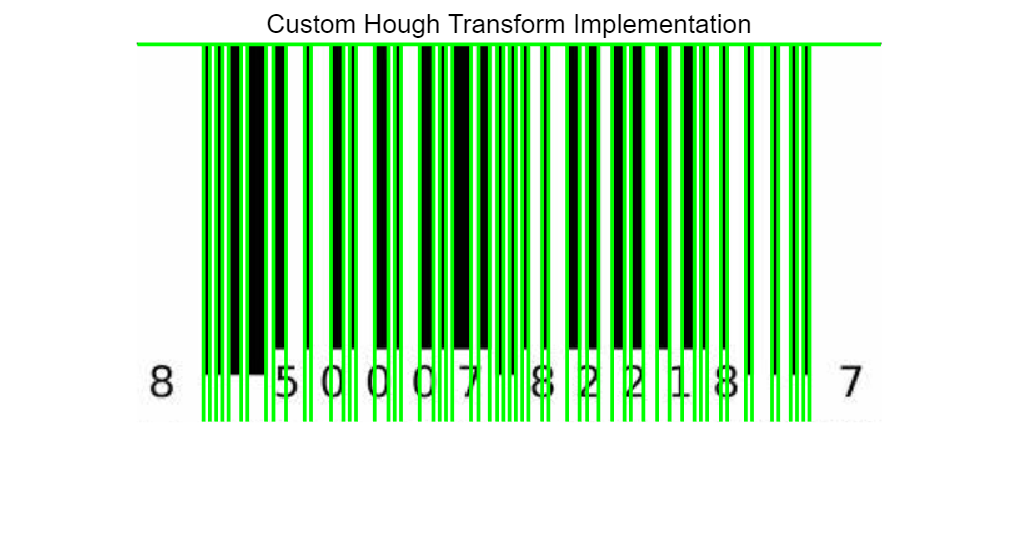

% TODO Place your solution here
% Select one image for this implementation

# ***Self-work***

**Answer questions and conclude your work results.**

## **Questions **

Please answer the following questions:

 -  What is the main principle of the Hough transform?

** > **The main principle of the Hough transform is to convert the problem of detecting shapes in image space into a problem of detecting peaks in parameter space. It works by having each edge point "vote" for all possible parameter combinations that could produce a shape passing through that point, then looking for parameter combinations that received many votes.

 - May the Hough transform be used to find arbitrary contours that cannot be described analytically?

** > **The standard Hough transform is designed for shapes with simple analytic descriptions (lines, circles, ellipses). For arbitrary shapes, the Generalized Hough Transform can be used, which uses a template-based approach rather than an analytic description.

 - What are the *recurrent* and *generalized* Hough transforms?

** > **The recurrent Hough transform is an iterative version that processes image subsets sequentially. The Generalized Hough Transform extends the concept to arbitrary shapes by using a reference table that describes the shape's characteristics relative to a reference point.

 -  What are the ways of parametrization in the Hough transform?

** > **

- For lines: (ρ,θ) polar coordinates

- For circles: (x,y,r) center coordinates and radius

- For ellipses: more complex parameter spaces including center, axes, and rotation angleThe choice depends on the shape being detected and computational constraints.

## **Conclusion**

What have you learned with this task? Don't forget to conclude it.

 **> **

- The importance of proper edge detection as a preprocessing step, with the Canny edge detector being particularly effective.

- The trade-offs between different Hough transform implementations - the classic version is more thorough but computationally expensive, while probabilistic versions are faster but may miss some features.

- The sensitivity of the Hough transform to parameter choices like threshold values, which must be carefully tuned for each image.

- The extension of the Hough transform concept from simple lines to more complex shapes like circles.

- The practical challenges in implementing the algorithm from scratch, particularly regarding computational efficiency.